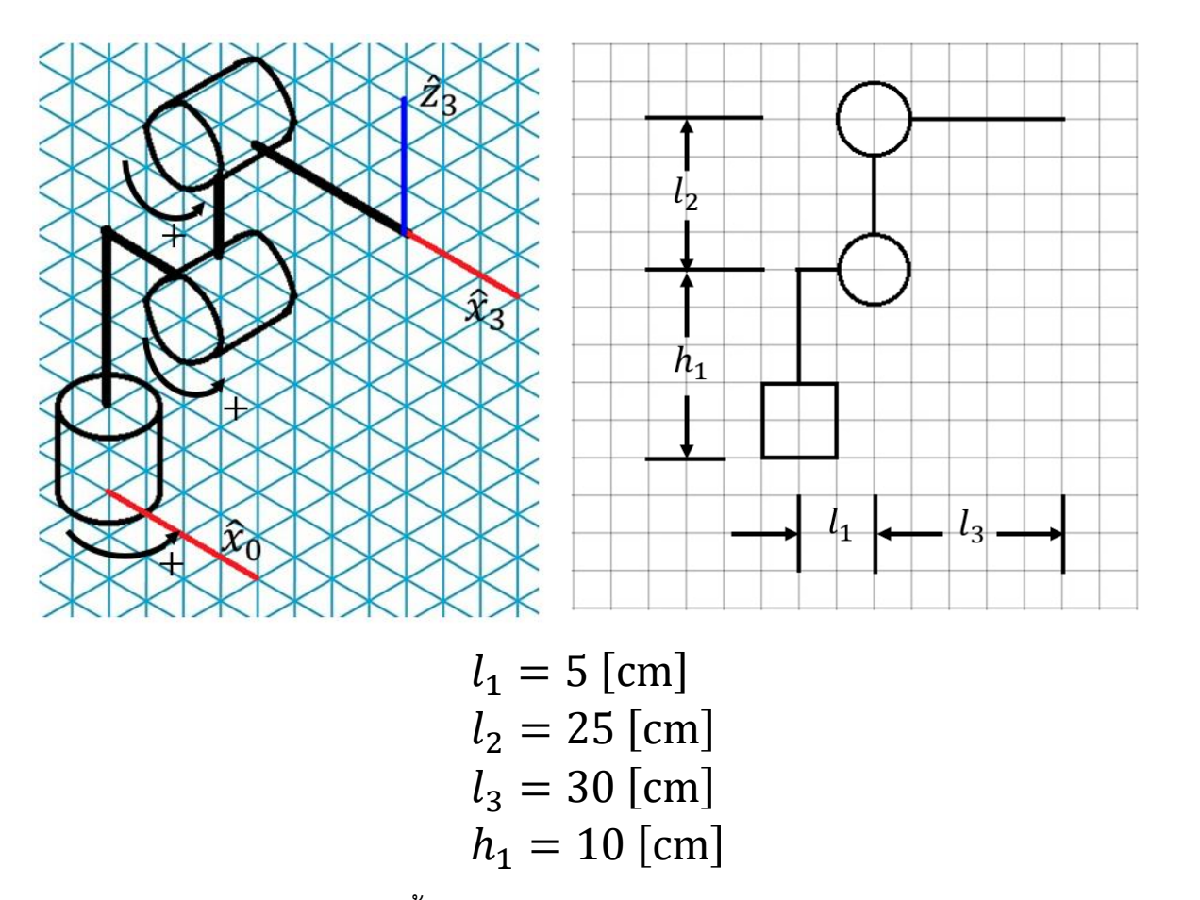                                                                                                                                                                                                                                

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

**task2jointConversion:** return alert 0: cant access, 1: accessable; via_point_joint (3x4xn) D2: possible joint, D3: No. input via_point task

      Description: check possible access + convert task to joint

**optimalPath: **return selected_via_point_joint (3xn)

alert =      1     1     1     1


via_point_joint = via_point_joint(:,:,1) =

         0         0   -3.1416   -3.1416
   -1.7521         0    0.4148    1.6096
    3.1416         0    2.6561    0.4855


via_point_joint(:,:,2) =

         0         0         0         0
   -1.5867   -1.3963         0         0
    1.7453    1.3963         0         0


via_point_joint(:,:,3) =

         0         0         0         0
   -0.8607         0         0         0
    2.3562    0.7854         0         0


via_point_joint(:,:,4) =

    3.1416    3.1416         0         0
   -0.8607         0         0         0
    2.3562    0.7854         0         0


p =          0         0         0         0
   -0.8607         0         0         0
    2.3562    0.7854         0         0


flag =      1     1     0     0
